clc
clear vars
%zmieniane rozmiarow zdj aby alexnet je mogl przyjac
imds=imageDatastore('Train','IncludeSubfolders',true,'LabelSource','foldernames')

imds =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00001.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00002.png'
                               ... and 39206 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 39206 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage




%dziele dane na zbior uczacy i testowy gdzie uczacy to 70 procent
[training, walidating, testing]=splitEachLabel(imds,0.7,0.15) 

training =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00001.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00000_00002.png'
                               ... and 27443 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 27443 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


walidating =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00027.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00028.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00004_00029.png'
                               ... and 5888 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 5888 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testing =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00005_00029.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00006_00000.png';
                              'C:\Users\Mike\Desktop\signs\Train\0\00000_00006_00001.png'
                               ... and 5869 more
                              }
                     Folders: {
                              'C:\Users\Mike\Desktop\signs\Train'
                              }
                      Labels: [0; 0; 0 ... and 5869 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


testlabel=testing.Labels

testlabel = 5872×1 categorical array
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


%ilosc class w sumie
classes=numel(categories(imds.Labels))

classes = 43

%zamienianie obrazu wejsciowego na wejscie alexnet
training=augmentedImageDatastore([227 227],training);
walidating=augmentedImageDatastore([227 227],walidating);
testing=augmentedImageDatastore([227 227],testing);
%stworzenie sieci na podstawie alexnet
net=alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers=net.Layers

layers =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0

%editowanie sieci aby classy byly tylko znaki
layers(end-2)=fullyConnectedLayer(classes)

layers =   25×1 Layer array with layers:

     1   'data'     Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0

layers(end)=classificationLayer

layers =   25×1 Layer array with layers:

     1   'data'    Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
 


%ustawienie tempo uczenia sie i maks epochs 2 i dodatkowo korzystam z
%zbioru walidacyjnego aby zapobiec przeuczeniu sie sieci jak i doskonalenia
options=trainingOptions('sgdm','InitialLearnRate',0.001,'MaxEpochs',2,'MiniBatchSize',32,'ValidationData',walidating)

options =   TrainingOptionsSGDM with properties:

                    Momentum: 0.9000
            InitialLearnRate: 1.0000e-03
           LearnRateSchedule: 'none'
         LearnRateDropFactor: 0.1000
         LearnRateDropPeriod: 10
            L2Regularization: 1.0000e-04
     GradientThresholdMethod: 'l2norm'
           GradientThreshold: Inf
                   MaxEpochs: 2
               MiniBatchSize: 32
                     Verbose: 1
            VerboseFrequency: 50
              ValidationData: [1×1 augmentedImageDatastore]
         ValidationFrequency: 50
          ValidationPatience: Inf
                     Shuffle: 'once'
              CheckpointPath: ''
        ExecutionEnvironment: 'auto'
                  WorkerLoad: []
                   OutputFcn: []
                       Plots: 'none'
              SequenceLength: 'longest'
        SequencePaddingValue: 0
    SequencePaddingDirectio

%uczenia sie
[signnet,info]=trainNetwork(training,layers,options)

Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:22 |        0.00% |        2.61% |       6.8128 |       4.4270 |          0.0010 |
|       1 |          50 |       00:00:54 |       28.13% |       38.02% |       2.2678 |       2.1457 |          0.0010 |
|       1 |         100 |       00:01:26 |       46.88% |       56.76% |       1.8323 |       1.3071 |          0.0010 |
|       1 |         150 |       00:01:58 |       65.63% |       69.92% |       0.9089 |   

signnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


info = struct with fields:
               TrainingLoss: [1×1714 double]
           TrainingAccuracy: [1×1714 double]
             ValidationLoss: [1×1714 double]
         ValidationAccuracy: [1×1714 double]
              BaseLearnRate: [1×1714 double]
        FinalValidationLoss: 0.1591
    FinalValidationAccuracy: 95.9090


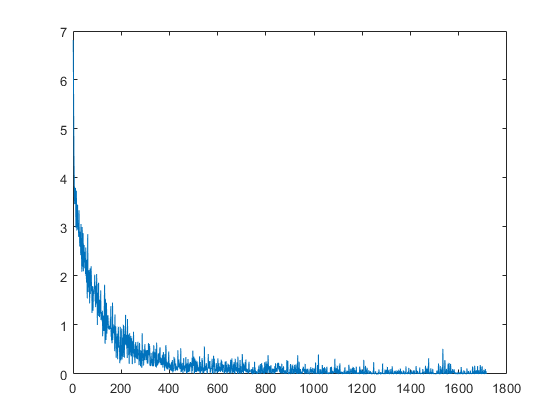


%wykres training loss
plot(info.TrainingLoss);

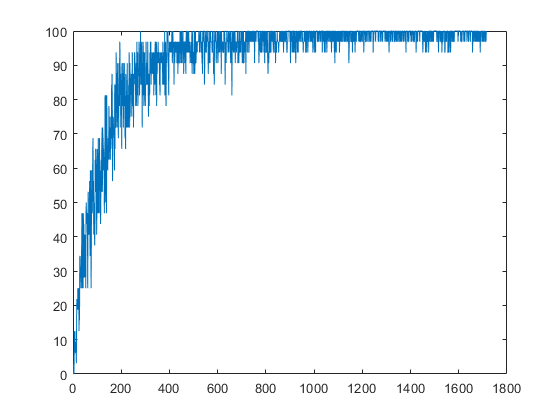

xlabel('Liczba iteracji')
ylabel('Strata małej partii')
%wykres traning dokładnoscz
plot(info.TrainingAccuracy);

xlabel('Liczba iteracji')
ylabel('Dokładność procentowa[%]')
%testowanie sieci na 30 procent danych
testpreds=classify(signnet,testing)

testpreds = 5872×1 categorical array
     0 
     1 
     1 
     0 
     1 
     0 
     1 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 
     0 


testactual=testlabel;
%ilośc dobrze sklasyfikowanych
numCorrect = nnz(testpreds == testactual)

numCorrect = 5649

%procent prawidłowo sklasyfikowanych
fracCorrect = numCorrect/numel(testpreds)

fracCorrect = 0.9620

%macierz pomyłek
fig = figure(1);
cc=confusionchart(testlabel,testpreds,'RowSummary','row-normalized','ColumnSummary','column-normalized')

cc =   ConfusionMatrixChart with properties:

    NormalizedValues: [43×43 double]
         ClassLabels: [43×1 categorical]

  Show all properties


xlabel('Klasy przewidziane')
ylabel('Klasy faktyczne')
cc.NormalizedValues

ans =     27     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   332     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   301     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   183     0     0     0     0     0     0     0     0     0     8     0     0     0     0     0     7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

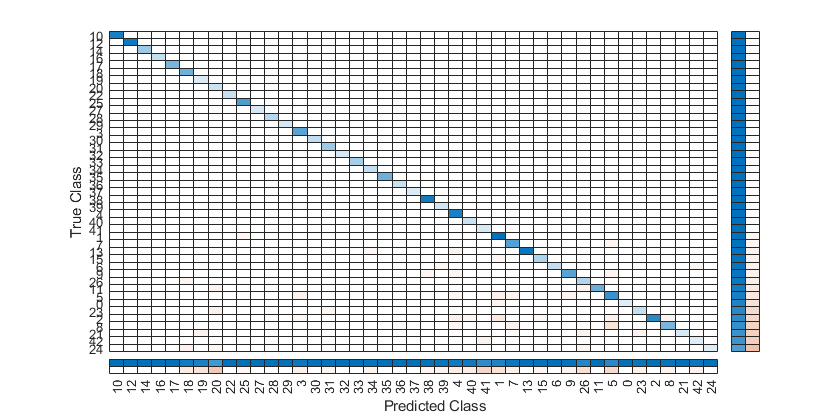

fig_Position = fig.Position;
fig_Position(3) = fig_Position(3)*1.5;
fig.Position = fig_Position;
%sortuje według czułości na osi x
cc.Normalization = 'row-normalized'; 
sortClasses(cc,'descending-diagonal')
cc.Normalization = 'absolute'; 

% sortuje według precyzji na osi x
fig2=figure(2);
cc=confusionchart(testlabel,testpreds,'RowSummary','row-normalized','ColumnSummary','column-normalized')

cc =   ConfusionMatrixChart with properties:

    NormalizedValues: [43×43 double]
         ClassLabels: [43×1 categorical]

  Show all properties


xlabel('Klasy przewidziane')
ylabel('Klasy faktyczne')
cc.NormalizedValues

ans =     27     4     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0   332     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   301     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0   183     0     0     0     0     0     0     0     0     0     8     0     0     0     0     0     7     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 

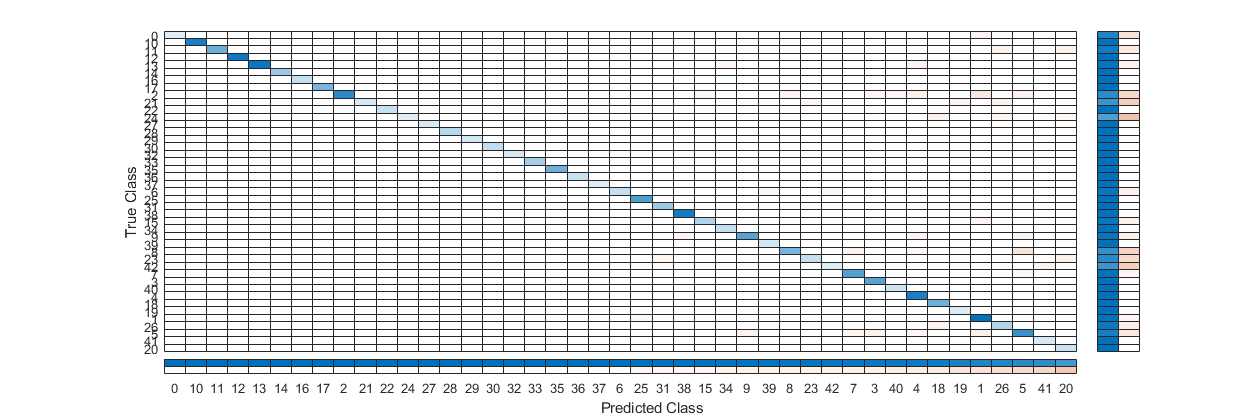

fig2_Position = fig.Position;
fig2_Position(3) = fig2_Position(3)*1.5;
fig2.Position = fig2_Position;
cc.Normalization = 'column-normalized';
sortClasses(cc,'descending-diagonal')
cc.Normalization = 'absolute';   